% clear variables in workspace and close all figures
clearvars; close all;

% reading the data
data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');
% data = readtimetable('../Datasets/Ontario/OntarioIESO.xlsx');

% TR = timerange('2016-01-01','2019-12-31');
% data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables

% y = (x - min) / (max - min)
tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

clearvars -except data ndata mindp maxdp


TR = timerange('2018-01-01','2020-01-01'); % 2018 - 2019
trainvald = ndata(TR, :);   % training data

TR = timerange('2020-01-01','2021-01-01'); % 2020
testd = ndata(TR, :);   % testing data

% TR = timerange('2016-01-01','2019-12-31');
% ndata = ndata(TR, :);   % new total dataset

## Training the Forecasters

### Inputs and Targets Creation


[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(trainvald);

% clearvars -except data ndata mindp maxdp clf_outputs blf_outputs inputs time_outputs p trainvald testd

### Base Load Forecaster training

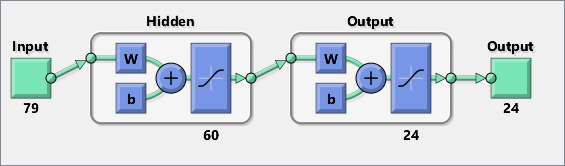

clear net

x = inputs;
t = blf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 60;   % 30 - 60
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';


% Train the Network
[net,trBLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = blf_outputs(:,trBLF.trainInd);
% val_set = blf_outputs(:,trBLF.valInd);
% test_set = blf_outputs(:,trBLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

blf_net = net;

### Change in the Load Forecaster Training

clear net

x = inputs;
t = clf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 60;   % 30 - 60
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';

% Train the Network
[net,trCLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = clf_outputs(:,trCLF.trainInd);
% val_set = clf_outputs(:,trCLF.valInd);
% test_set = clf_outputs(:,trCLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

clf_net = net;

## Predict the test dataset

% Generating the inputs for the entire dataset
[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(testd);

### Generate BLF forecasts

% generate the forecasts
raw_blf = blf_net(inputs);

% denormalize predicted values
yBLF = raw_blf * (maxdp(1) - mindp(1)) + mindp(1);

% these are the actual, denormalized load demand values 
actuals = blf_outputs * (maxdp(1) - mindp(1)) + mindp(1);

### Generate CLF forecasts

% generate the forecasts
raw_clf = clf_net(inputs) + p(:,1:end-1);

% denormalize predicted values
yCLF = raw_clf * (maxdp(1) - mindp(1)) + mindp(1);

### Generate RLS forecasts

days = size(yBLF);
days = days(2);

% calls the rls combiner function
yRLS = RLS_Combiner(raw_blf, raw_clf, blf_outputs, days); % uses normalized values as inputs

% denormalize the rls combination
yRLS = yRLS*(maxdp(1) - mindp(1)) + mindp(1);

### Calculate errors

[Metrics,eBLF, blf_AEs, blf_APEs, eCLF, clf_AEs, clf_APEs,...
eRLS, rls_AEs, rls_APEs, blf_MAPE, clf_MAPE, rls_MAPE] = ErrorMetrics(actuals, yBLF, yCLF, yRLS);

Metrics

Metrics = 6×4 table
                   Metrics                      BLF        CLF         RLS   
    ______________________________________    _______    _______    _________

    {'MAPE - Mean Absolute Percent Error'}     5.5424     4.3615       3.7859
    {'ME - Mean Error'                   }    -1.9021    -1.0891    0.0074017
    {'MAE - Mean Absolute Error'         }     5.1981     4.3701       3.8353
    {'MSE - Mean Squared Error'          }     50.264     35.623       28.867
    {'RMSE - Root Mean Squared Error'    }     7.0897     5.9685       5.3728
    {'Standard Deviation'                }     6.8302     5.8686       5.3731


### Plots of the Test dataset

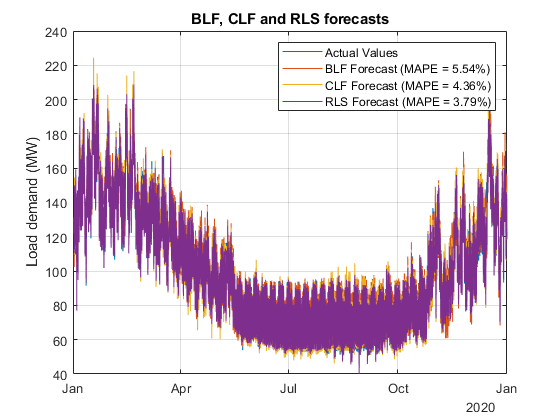

figure;

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('BLF, CLF and RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot blf forecast
DisplayName = num2str(blf_MAPE, 'BLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yBLF(:), 'DisplayName', DisplayName)

% plot clf forecast
DisplayName = num2str(clf_MAPE, 'CLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yCLF(:), 'DisplayName', DisplayName)

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(time_outputs,yRLS(:), 'DisplayName', DisplayName)
legend('show')

## Performance Analysis of the Algorithms

### Hourly Horizon

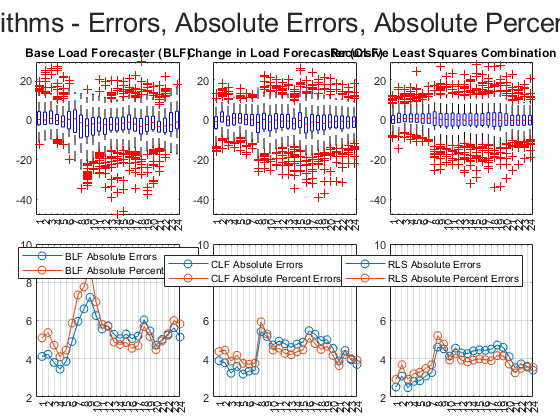

% helps to align the y axes
tmp = [eBLF; eCLF; eRLS];
ymax = max(tmp(:));
ymin = min(tmp(:));
% ylim([ymin ymax])


figure;
time24 = time_outputs.Hour + 1; % Time = 1...24 hrs
t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Hourly horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), time24)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), time24)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), time24)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots     
sp(1) = nexttile;
stats = grpstats(blf_AEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('BLF Absolute Errors','BLF Absolute Percent Errors', 'Location','best')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('CLF Absolute Errors','CLF Absolute Percent Errors', 'Location','northeast')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), time_outputs.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('RLS Absolute Errors','RLS Absolute Percent Errors', 'Location','northeast')
grid on
linkaxes(sp)

### Daily Horizon

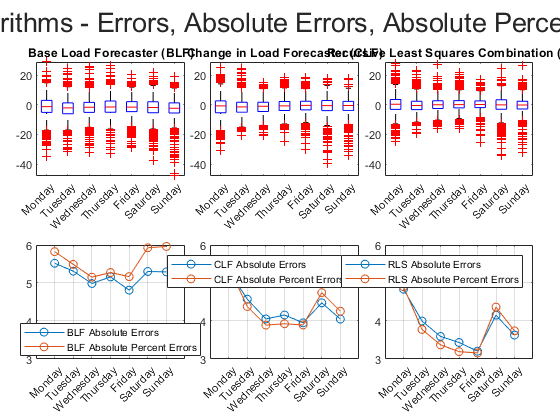

% helps to align the y axes
tmp = [eBLF; eCLF; eRLS];
ymax = max(tmp(:));
ymin = min(tmp(:));
% ylim([ymin ymax])


figure;
[dnum, dname] = weekday(time_outputs, 'long');
labels = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Daily horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun

nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), dnum,'positions', xtick)
set(gca, 'XTickLabel', labels)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots    
sp(1) = nexttile;
stats = grpstats(blf_AEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labels)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('BLF Absolute Errors','BLF Absolute Percent Errors', 'Location','best')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('CLF Absolute Errors','CLF Absolute Percent Errors', 'Location','northeast')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labels)
legend('RLS Absolute Errors','RLS Absolute Percent Errors', 'Location','northeast')
grid on
linkaxes(sp, 'y')

### Monthly Horizon

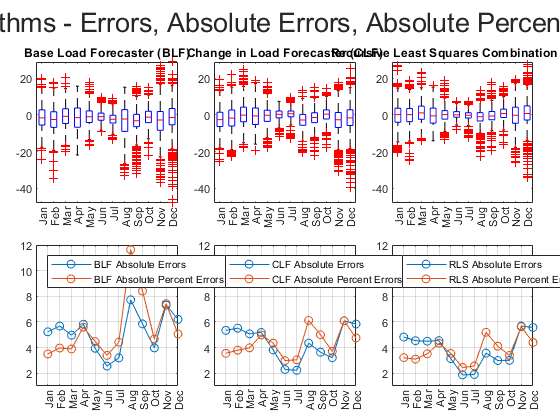

% helps to align the y axes
tmp = [eBLF; eCLF; eRLS];
ymax = max(tmp(:));
ymin = min(tmp(:));
% ylim([ymin ymax])


figure;
labels = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the Algorithms - Errors, Absolute Errors, Absolute Percent Errors - Monthly horizons");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


% Box plots of the error distribution
nexttile
% sp(1) = nexttile;
boxplot(eBLF(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Base Load Forecaster (BLF)')

nexttile
% sp(2) = nexttile;
boxplot(eCLF(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Change in Load Forecaster (CLF)')

nexttile
% sp(3) = nexttile;
boxplot(eRLS(:), time_outputs.Month, 'Labels', labels)
ylim([ymin ymax])
title('Recursive Least Squares Combination (RLS)')
% linkaxes(sp)


% Absolute Errors plots   
sp(1) = nexttile;
stats = grpstats(blf_AEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('BLF Absolute Errors')
grid
hold on

sp(2) = nexttile;
stats = grpstats(clf_AEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('CLF Absolute Errors')
grid
hold on

sp(3) = nexttile;
stats = grpstats(rls_AEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


% Absolute Percent Errors plot
sp(1) = nexttile(4);
stats = grpstats(blf_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('BLF Absolute Errors','BLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(2) = nexttile(5);
stats = grpstats(clf_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('CLF Absolute Errors','CLF Absolute Percent Errors', 'Location','northwest')
grid on

sp(3) = nexttile(6);
stats = grpstats(rls_APEs(:), time_outputs.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labels)
legend('RLS Absolute Errors','RLS Absolute Percent Errors', 'Location','northwest')
grid on
linkaxes(sp, 'y')

## Performance Analysis - RLS Combiner (Hourly, Daily, Monthly)

dt = time_outputs;    % DateTime of the test dataset
errors = eRLS(:);

figure;
time24 = dt.Hour + 1; % Time = 1...24 hrs
[dnum, dname] = weekday(dt, 'long');
labeld = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};
labelm = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug',...
          'Sep', 'Oct', 'Nov', 'Dec'};

t = tiledlayout(2,3);
t.Padding = 'compact';     % uses all the spaces in the figure window
t.TileSpacing = 'compact';
sgt = sgtitle("Performance of the RLS ANNSTLF Algorithm - Errors, Absolute Errors, Absolute Percent Errors");
sgt.FontSize = 20;
warning('off', 'MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout');


### Box plots of the error distribution

% Hourly
sp(1) = nexttile;
boxplot(errors, time24)
title('Hourly Horizon')

% Daily
xtick = [7,1,2,3,4,5,6];    % the position we want them displayed as, i.e Mon - Sun
sp(2) = nexttile;
boxplot(errors, dnum,'positions', xtick)
set(gca, 'XTickLabel', labeld)
title('Daily Horizon')

% Monthly
sp(3) = nexttile;
boxplot(errors, dt.Month, 'Labels', labelm)
title('Monthly Horizon')

linkaxes(sp, 'y')
clear sp


### Absolute Errors plots 

% Absolute Errors plots    
AE = rls_AEs(:);   % divided by 100, so I can fit multiple charts

% Hourly
sp(1) = nexttile;
stats = grpstats(AE, dt.Hour, "mean");
plot(stats, '-o')
grid
hold on

% Daily
sp(2) = nexttile;
stats = grpstats(AE, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca, "XTickLabel", labeld)
grid
hold on

% Monthly
sp(3) = nexttile;
stats = grpstats(AE, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
% legend('RLS Absolute Errors')
grid
hold on
% linkaxes(sp)
clear sp


### Absolute Percent Errors plot

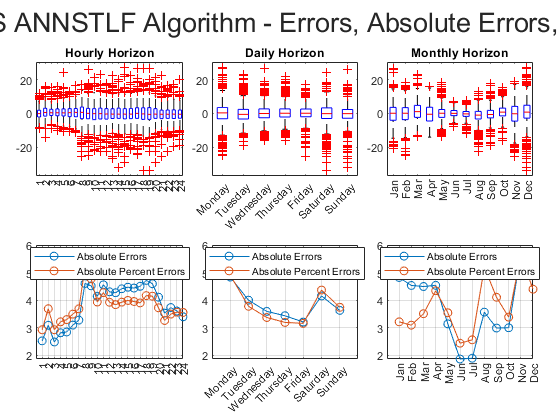

APEs = rls_APEs(:);

% Hourly
sp(1) = nexttile(4);
stats = grpstats(APEs, dt.Hour, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:24)
legend('Absolute Errors','Absolute Percent Errors', 'Location','best')
grid on

sp(2) = nexttile(5);
stats = grpstats(APEs, dnum, "mean");
stats = [stats(2:7); stats(1)];     % aligns for Mon - Sun
plot(stats, '-o')
set(gca,'XTick',1:1:7)
set(gca, "XTickLabel", labeld)
legend('Absolute Errors','Absolute Percent Errors', 'Location','best')
grid on

sp(3) = nexttile(6);
stats = grpstats(APEs, dt.Month, "mean");
plot(stats, '-o')
set(gca,'XTick',1:1:12)
set(gca,'XTickLabel', labelm)
legend('Absolute Errors','Absolute Percent Errors', 'Location','best')
grid on
linkaxes(sp, 'y')